clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[8.250;13.526;18.525];
u31=[0.340;0.563;0.753];
r2=[19.804;13.526;18.525];
u32=[0.340;0.563;0.753];
r3=[2.473;18.406;28.643];
u33=[0.340;-0.563;-0.753];
r4=[3.305;7.762;28.643];
u34=[-0.340;-0.563;-0.753];
r5=[14.859;7.762;28.643];
u35=[-0.340;-0.563;-0.753];
r6=[-2.473;2.882;18.525];
u36=[-0.340;0.563;0.753];
r7=[9.082;2.882;18.525];
u37=[-0.340;0.563;0.753];
r8=[2.473;13.526;5.059];
u38=[0.340;0.563;-0.753];



x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];

hold on 
axis([0 15 0 15]);

for R3=2.4:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     9.4000    2.4000    1.0019


ans =     7.9000    2.7000    1.0014


ans =     7.1500    3.0000    1.0057


ans =     6.7500    3.3000    1.0019


ans =     6.4500    3.6000    1.0071


ans =     6.2500    3.9000    1.0092


ans =     6.1000    4.2000    1.0119


ans =     6.0000    4.5000    1.0104


ans =     5.9500    4.8000    1.0012


ans =     5.8500    5.1000    1.0108


ans =     5.8000    5.4000    1.0097


ans =     5.7500    5.7000    1.0115


ans =     5.7000    6.0000    1.0156


ans =     5.7000    6.3000    1.0057


ans =     5.6500    6.6000    1.0132


ans =     5.6500    6.9000    1.0056


ans =     5.6000    7.2000    1.0156


ans =     5.6000    7.5000    1.0098


ans =     5.6000    7.8000    1.0046


ans =     5.5500    8.1000    1.0170


ans =     5.5500    8.4000    1.0129


ans =     5.5500    8.7000    1.0092


ans =     5.5500    9.0000    1.0058


ans =     5.5500    9.3000    1.0028


ans =     5.5500    9.6000    1.0001


ans =     5.5000    9.9000    1.0151


ans =     5.5000   10.2000    1.0128


ans =     5.5000   10.5000    1.0107


ans =     5.5000   10.8000    1.0088


ans =     5.5000   11.1000    1.0070


ans =     5.5000   11.4000    1.0054


ans =     5.5000   11.7000    1.0039


ans =     5.5000   12.0000    1.0025


ans =     5.5000   12.3000    1.0012


ans =     5.5000   12.6000    1.0000


ans =     5.4500   12.9000    1.0169



scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')

for R3=4:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =    13.0000    4.0000    1.0038


ans =    12.2500    4.3000    1.0040


ans =    11.4500    4.6000    1.0028


ans =    10.6000    4.9000    1.0002


ans =     9.6500    5.2000    1.0007


ans =     8.6500    5.5000    1.0024


ans =     7.7000    5.8000    1.0018


ans =     6.8500    6.1000    1.0004


ans =     6.1000    6.4000    1.0028


ans =     5.5500    6.7000    1.0001


ans =     5.0500    7.0000    1.0064


ans =     4.7000    7.3000    1.0053


ans =     4.4000    7.6000    1.0064


ans =     4.1500    7.9000    1.0068


ans = 1×3
    3.9500    8.2000    1.0036


ans = 1×3
    3.7500    8.5000    1.0053


ans = 1×3
    3.5500    8.8000    1.0116


ans = 1×3
    3.4000    9.1000    1.0092


ans = 1×3
    3.2500    9.4000    1.0094


ans = 1×3
    3.1000    9.7000    1.0118


ans = 1×3
    3.0000   10.0000    1.0025


ans = 1×3
    2.8500   10.3000    1.0084


ans = 1×3
    2.7500   10.6000    1.0017


ans = 1×3
    2.6000   10.9000    1.0107


ans = 1×3
    2.5000   11.2000    1.0066


ans = 1×3
    2.4000   11.5000    1.0037


ans = 1×3
    2.3000   11.8000    1.0022


ans = 1×3
    2.2000   12.1000    1.0023


ans = 1×3
    2.1000   12.4000    1.0044


ans = 1×3
    2.0000   12.7000    1.0090


ans = 1×3
    1.9000   13.0000    1.0167



scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','13')

for R3=3:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    6.9000    3.0000    1.0036


ans = 1×3
    6.7500    3.3000    1.0047


ans = 1×3
    6.6500    3.6000    1.0036


ans = 1×3
    6.5500    3.9000    1.0095


ans = 1×3
    6.5000    4.2000    1.0069


ans = 1×3
    6.4500    4.5000    1.0077


ans = 1×3
    6.4000    4.8000    1.0113


ans = 1×3
    6.4000    5.1000    1.0023


ans = 1×3
    6.3500    5.4000    1.0095


ans = 1×3
    6.3500    5.7000    1.0032


ans = 1×3
    6.3000    6.0000    1.0128


ans = 1×3
    6.3000    6.3000    1.0081


ans = 1×3
    6.3000    6.6000    1.0041


ans = 1×3
    6.3000    6.9000    1.0005


ans = 1×3
    6.2500    7.2000    1.0129


ans = 1×3
    6.2500    7.5000    1.0101


ans = 1×3
    6.2500    7.8000    1.0077


ans = 1×3
    6.2500    8.1000    1.0056


ans = 1×3
    6.2500    8.4000    1.0036


ans = 1×3
    6.2500    8.7000    1.0019


ans = 1×3
    6.2500    9.0000    1.0003


ans = 1×3
    6.2000    9.3000    1.0147


ans = 1×3
    6.2000    9.6000    1.0134


ans = 1×3
    6.2000    9.9000    1.0123


ans = 1×3
    6.2000   10.2000    1.0112


ans = 1×3
    6.2000   10.5000    1.0102


ans = 1×3
    6.2000   10.8000    1.0093


ans = 1×3
    6.2000   11.1000    1.0085


ans = 1×3
    6.2000   11.4000    1.0077


ans = 1×3
    6.2000   11.7000    1.0070


ans = 1×3
    6.2000   12.0000    1.0063


ans = 1×3
    6.2000   12.3000    1.0057


ans = 1×3
    6.2000   12.6000    1.0052


ans = 1×3
    6.2000   12.9000    1.0047



scatter(x3,y3,10,'markerfacecolor',[63, 125, 162]/256,...
        'markeredgecolor',[63, 125, 162]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','14')

for R3=4:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
   10.3500    4.0000    1.0003


ans = 1×3
    9.1000    4.3000    1.0012


ans = 1×3
    8.3500    4.6000    1.0034


ans = 1×3
    7.8500    4.9000    1.0058


ans = 1×3
    7.5000    5.2000    1.0072


ans = 1×3
    7.2500    5.5000    1.0064


ans = 1×3
    7.0500    5.8000    1.0070


ans = 1×3
    6.9000    6.1000    1.0057


ans = 1×3
    6.7500    6.4000    1.0107


ans = 1×3
    6.6500    6.7000    1.0098


ans = 1×3
    6.6000    7.0000    1.0010


ans = 1×3
    6.5000    7.3000    1.0071


ans = 1×3
    6.4500    7.6000    1.0036


ans = 1×3
    6.4000    7.9000    1.0023


ans = 1×3
    6.3500    8.2000    1.0027


ans = 1×3
    6.3000    8.5000    1.0048


ans = 1×3
    6.2500    8.8000    1.0083


ans = 1×3
    6.2000    9.1000    1.0132


ans = 1×3
    6.2000    9.4000    1.0049


ans = 1×3
    6.1500    9.7000    1.0117


ans = 1×3
    6.1500   10.0000    1.0048


ans = 1×3
    6.1000   10.3000    1.0133


ans = 1×3
    6.1000   10.6000    1.0075


ans = 1×3
    6.1000   10.9000    1.0022


ans = 1×3
    6.0500   11.2000    1.0124


ans = 1×3
    6.0500   11.5000    1.0079


ans = 1×3
    6.0500   11.8000    1.0038


ans = 1×3
    6.0000   12.1000    1.0154


ans = 1×3
    6.0000   12.4000    1.0118


ans = 1×3
    6.0000   12.7000    1.0085


ans = 1×3
    6.0000   13.0000    1.0054



scatter(x4,y4,10,'markerfacecolor',[237, 125, 49]/256,...
        'markeredgecolor',[237, 125, 49]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','15')

for R3=4:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];   
end

ans = 1×3
    9.6000    4.0000    1.0008


ans = 1×3
    9.2500    4.3000    1.0059


ans = 1×3
    9.0000    4.6000    1.0015


ans = 1×3
    8.7500    4.9000    1.0024


ans = 1×3
    8.5500    5.2000    1.0003


ans = 1×3
    8.3500    5.5000    1.0028


ans = 1×3
    8.2000    5.8000    1.0006


ans = 1×3
    8.0500    6.1000    1.0020


ans = 1×3
    7.9000    6.4000    1.0065


ans = 1×3
    7.8000    6.7000    1.0041


ans = 1×3
    7.7000    7.0000    1.0039


ans = 1×3
    7.6000    7.3000    1.0055


ans = 1×3
    7.5000    7.6000    1.0088


ans = 1×3
    7.4500    7.9000    1.0029


ans = 1×3
    7.3500    8.2000    1.0087


ans = 1×3
    7.3000    8.5000    1.0047


ans = 1×3
    7.2500    8.8000    1.0015


ans = 1×3
    7.1500    9.1000    1.0100


ans = 1×3
    7.1000    9.4000    1.0080


ans = 1×3
    7.0500    9.7000    1.0065


ans = 1×3
    7.0000   10.0000    1.0054


ans = 1×3
    6.9500   10.3000    1.0046


ans = 1×3
    6.9000   10.6000    1.0041


ans = 1×3
    6.8500   10.9000    1.0039


ans = 1×3
    6.8000   11.2000    1.0040


ans = 1×3
    6.7500   11.5000    1.0042


ans = 1×3
    6.7000   11.8000    1.0047


ans = 1×3
    6.6500   12.1000    1.0053


ans = 1×3
    6.6000   12.4000    1.0060


ans = 1×3
    6.5500   12.7000    1.0069


ans = 1×3
    6.5000   13.0000    1.0080



scatter(x5,y5,10,'markerfacecolor',[47, 85, 151]/256,...
        'markeredgecolor',[47, 85, 151]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','16')

for R3=3:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];   
end

ans = 1×3
    7.6500    3.0000    1.0038


ans = 1×3
    7.2000    3.3000    1.0044


ans = 1×3
    6.8000    3.6000    1.0013


ans = 1×3
    6.4000    3.9000    1.0066


ans = 1×3
    6.1000    4.2000    1.0035


ans = 1×3
    5.8500    4.5000    1.0006


ans = 1×3
    5.6000    4.8000    1.0081


ans = 1×3
    5.4500    5.1000    1.0017


ans = 1×3
    5.3000    5.4000    1.0027


ans = 1×3
    5.1500    5.7000    1.0108


ans = 1×3
    5.0500    6.0000    1.0109


ans = 1×3
    5.0000    6.3000    1.0006


ans = 1×3
    4.9000    6.6000    1.0093


ans = 1×3
    4.8500    6.9000    1.0056


ans = 1×3
    4.8000    7.2000    1.0046


ans = 1×3
    4.7500    7.5000    1.0059


ans = 1×3
    4.7000    7.8000    1.0094


ans = 1×3
    4.6500    8.1000    1.0147


ans = 1×3
    4.6500    8.4000    1.0033


ans = 1×3
    4.6000    8.7000    1.0115


ans = 1×3
    4.6000    9.0000    1.0021


ans = 1×3
    4.5500    9.3000    1.0127


ans = 1×3
    4.5500    9.6000    1.0049


ans = 1×3
    4.5000    9.9000    1.0174


ans = 1×3
    4.5000   10.2000    1.0109


ans = 1×3
    4.5000   10.5000    1.0048


ans = 1×3
    4.4500   10.8000    1.0196


ans = 1×3
    4.4500   11.1000    1.0145


ans = 1×3
    4.4500   11.4000    1.0097


ans = 1×3
    4.4500   11.7000    1.0052


ans = 1×3
    4.4500   12.0000    1.0011


ans = 1×3
    4.4000   12.3000    1.0183


ans = 1×3
    4.4000   12.6000    1.0148


ans = 1×3
    4.4000   12.9000    1.0114



scatter(x6,y6,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','17')

for R3=3:0.3:13 %离心率
    R1=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];   
end

ans = 1×3
   10.5000    3.0000    1.0032


ans = 1×3
   10.3500    3.3000    1.0005


ans = 1×3
   10.1500    3.6000    1.0053


ans = 1×3
   10.0000    3.9000    1.0011


ans = 1×3
    9.8000    4.2000    1.0039


ans = 1×3
    9.6000    4.5000    1.0054


ans = 1×3
    9.4000    4.8000    1.0055


ans = 1×3
    9.2000    5.1000    1.0041


ans = 1×3
    9.0000    5.4000    1.0011


ans = 1×3
    8.7500    5.7000    1.0041


ans = 1×3
    8.5000    6.0000    1.0052


ans = 1×3
    8.2500    6.3000    1.0045


ans = 1×3
    8.0000    6.6000    1.0022


ans = 1×3
    7.7000    6.9000    1.0054


ans = 1×3
    7.4500    7.2000    1.0001


ans = 1×3
    7.1500    7.5000    1.0005


ans = 1×3
    6.8500    7.8000    1.0000


ans = 1×3
    6.5000    8.1000    1.0059


ans = 1×3
    6.2000    8.4000    1.0050


ans = 1×3
    5.9000    8.7000    1.0049


ans = 1×3
    5.6000    9.0000    1.0063


ans = 1×3
    5.3500    9.3000    1.0026


ans = 1×3
    5.1000    9.6000    1.0014


ans = 1×3
    4.8500    9.9000    1.0035


ans = 1×3
    4.6500   10.2000    1.0008


ans = 1×3
    4.4500   10.5000    1.0017


ans = 1×3
    4.2500   10.8000    1.0067


ans = 1×3
    4.1000   11.1000    1.0058


ans = 1×3
    3.9500   11.4000    1.0088


ans = 1×3
    3.8500   11.7000    1.0037


ans = 1×3
    3.7500   12.0000    1.0015


ans = 1×3
    3.6500   12.3000    1.0023


ans = 1×3
    3.5500   12.6000    1.0063


ans = 1×3
    3.4500   12.9000    1.0136


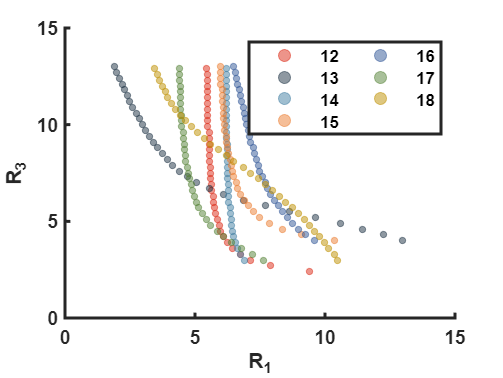


scatter(x7,y7,10,'markerfacecolor',[191, 144, 0]/256,...
        'markeredgecolor',[191, 144, 0]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','18')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);

hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end



